%Εργασία 1η

%Μαρία Γεωργακάκη
%Σταυρούλα Τσικοπούλου
%Αθανασία Καπουσούζη
%Νικόλας Πούλιος


%Askisi 1
clc; clear;

[x, Fs]=audioread('guit1.wav');

X=frame_wind(x, 256, 0.5)

X =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0


%erwtima c
y=frame_recon(X, 0.5)

y =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000         0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000   -0.0001   -0.0000   -0.0000   -0.0000   -0.0001   -0.0000   -0.0000   -0.0000         0         0   -0.0000   -0.0000



soundsc(x, Fs)
soundsc(y, Fs)
%παρατηρουμε πως δεν υπαρχει διαφορά στους δυο ηχους

%Askisi 2
clc; clear;

%Erwtima a
[x, Fs]=audioread('piano.wav');
%soundsc(x, Fs)
X=frame_wind(x, 512, 0.25)

X =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000   -0.0000         0   -0.0000    0.0000         0         0    0.0000         0         0    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0


XF=fft(X)

XF =   -0.0022 + 0.0000i  -0.0021 + 0.0000i  -0.0019 + 0.0000i  -0.0018 + 0.0000i  -0.0019 + 0.0000i  -0.0020 + 0.0000i  -0.0019 + 0.0000i  -0.0019 + 0.0000i  -0.0020 + 0.0000i  -0.0019 + 0.0000i  -0.0019 + 0.0000i  -0.1058 + 0.0000i  -0.0656 + 0.0000i   0.1664 + 0.0000i  -0.1056 + 0.0000i   0.2567 + 0.0000i   0.3554 + 0.0000i  -0.0533 + 0.0000i   0.0305 + 0.0000i   0.2929 + 0.0000i   0.3172 + 0.0000i   0.0062 + 0.0000i  -0.0061 + 0.0000i  -0.2338 + 0.0000i  -0.2592 + 0.0000i  -0.0051 + 0.0000i   0.2407 + 0.0000i  -0.0522 + 0.0000i  -0.1166 + 0.0000i  -0.0301 + 0.0000i   0.0861 + 0.0000i   0.0317 + 0.0000i  -0.0800 + 0.0000i   0.1774 + 0.0000i   0.1546 + 0.0000i  -0.0138 + 0.0000i  -0.0191 + 0.0000i  -0.0183 + 0.0000i   0.0354 + 0.0000i   0.1895 + 0.0000i   0.0290 + 0.0000i  -0.0050 + 0.0000i  -0.0978 + 0.0000i  -0.0119 + 0.0000i   0.1693 + 0.0000i   0.1654 + 0.0000i   0.0703 + 0.0000i  -0.0760 + 0.0000i  -0.0209 + 0.0000i   0.0432 + 0.0000i
   0.0011 - 0.0000i   0.0011 + 0.0001i   0.0


XFmag=abs(XF)%πλατος fft

XFmag =     0.0022    0.0021    0.0019    0.0018    0.0019    0.0020    0.0019    0.0019    0.0020    0.0019    0.0019    0.1058    0.0656    0.1664    0.1056    0.2567    0.3554    0.0533    0.0305    0.2929    0.3172    0.0062    0.0061    0.2338    0.2592    0.0051    0.2407    0.0522    0.1166    0.0301    0.0861    0.0317    0.0800    0.1774    0.1546    0.0138    0.0191    0.0183    0.0354    0.1895    0.0290    0.0050    0.0978    0.0119    0.1693    0.1654    0.0703    0.0760    0.0209    0.0432
    0.0011    0.0011    0.0009    0.0009    0.0010    0.0010    0.0009    0.0010    0.0010    0.0010    0.0009    0.1037    0.1464    0.2422    0.6888    0.7989    0.9496    0.2799    1.0601    0.8812    0.8022    0.3767    0.7858    0.5506    0.7088    0.7271    0.2554    0.5688    0.5219    0.4225    0.4869    0.5451    0.4041    0.2595    0.2569    0.3322    0.2551    0.3891    0.2725    0.2282    0.0653    0.2845    0.1188    0.3766    0.2039    0.1038    0.2609    0.1621    0.2167 

XFphase=imag(XF)%φαση fft

XFphase =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000    0.0001    0.0001   -0.0000   -0.0001    0.0001    0.0000   -0.0000    0.0000    0.0001   -0.0000   -0.0797    0.1439    0.0846   -0.4784    0.7750   -0.8821    0.2792   -0.2556    0.4414   -0.3179    0.1515    0.0166   -0.1320    0.2633    0.1254    0.2549   -0.4722    0.4381   -0.3835    0.4745   -0.5353    0.4036   -0.1587    0.0736   -0.3194    0.2184   -0.3400    0.2584   -0.2114   -0.0528   -0.0009   -0.0874    0.2274    0.0438    0.0508   -0.0315   -0.0111    0.148


%Erwtima b
[rows, cols]=size(XFmag);

for f=1:rows
    for k=1:cols
        if k==1
            dE(f,k)=XFmag(f,k);
        else
            dE(f,k)=XFmag(f,k)-XFmag(f, k-1);
        end
    end
end
dE

dE =     0.0022   -0.0001   -0.0002   -0.0001    0.0001    0.0000   -0.0001    0.0000    0.0000   -0.0001   -0.0001    0.1040   -0.0402    0.1008   -0.0608    0.1511    0.0987   -0.3021   -0.0228    0.2624    0.0243   -0.3110   -0.0001    0.2278    0.0253   -0.2541    0.2356   -0.1885    0.0644   -0.0865    0.0560   -0.0544    0.0483    0.0975   -0.0228   -0.1408    0.0052   -0.0008    0.0171    0.1541   -0.1605   -0.0239    0.0928   -0.0860    0.1574   -0.0038   -0.0952    0.0058   -0.0551    0.0223
    0.0011    0.0000   -0.0002   -0.0000    0.0001    0.0000   -0.0001    0.0001    0.0000   -0.0001   -0.0000    0.1028    0.0427    0.0958    0.4466    0.1101    0.1507   -0.6697    0.7802   -0.1788   -0.0791   -0.4255    0.4092   -0.2352    0.1582    0.0184   -0.4717    0.3133   -0.0469   -0.0994    0.0644    0.0582   -0.1410   -0.1446   -0.0026    0.0753   -0.0771    0.1341   -0.1166   -0.0443   -0.1629    0.2192   -0.1657    0.2578   -0.1727   -0.1002    0.1571   -0.0988    0.0546   -


for f=1:rows
    DE=abs(sum(dE));
end
DE

DE =     0.1903    0.0037    0.0028    0.0079    0.0037    0.0049    0.0004    0.0013    0.0035    0.0145    0.0062    8.8711  152.0900  266.2648  100.4020   46.4536   18.4498   16.3818    7.4273   32.9925    5.2084    5.7508   21.0371   11.2295   16.3901   27.9308   27.2983    1.0662    9.8529    3.2557    6.8639    4.7504    6.2387    4.9631    3.5458    3.1967   11.0501   13.6854   17.7246   17.7726   10.4263    7.5764    2.0776    2.7643    5.5061    9.6626   11.2943    4.0857    4.6910    5.3810


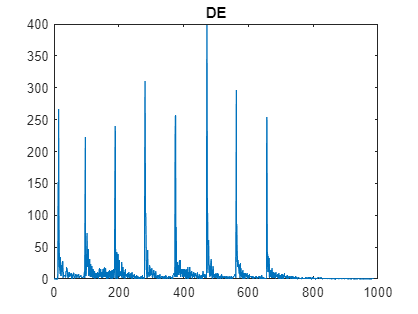

plot(DE)
title('DE')

%το καθε peak δειχνει την στιγμη που πατιεται μια νεα νοτα

%Erwtima C.a
[rows1, cols1]=size(XFphase);

for f=1:rows1
    for k=1:cols1
        if k==2
            dF(f,k)=wrapToPi(XFphase(f,k))-wrapToPi(2*XFphase(f,k-1));
        else if k==1
                dF(f,k)=wrapToPi(XFphase(f,k));
        else
            dF(f,k)=wrapToPi(XFphase(f,k))-wrapToPi(2*XFphase(f,k-1)-XFphase(f, k-2));
        end
        end
    end
end
dF

dF =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.0000    0.0001   -0.0001   -0.0001    0.0000    0.0002   -0.0002    0.0000    0.0001    0.0000   -0.0001   -0.0796    0.3032   -0.2828   -0.5038    1.8164   -2.9105    2.8184   -1.6961    1.2319   -1.4563    1.2288   -0.6044   -0.0138    0.5440   -0.5332    0.2674   -0.8565    1.6373   -1.7319    1.6797   -1.8679    1.9487   -1.5012    0.7946   -0.6253    0.9307   -1.0962    1.1569   -1.0683    0.6284   -0.1068   -0.1384    0.4014   -0.4984    0.1905   -0.0892    0.1026    0.1395   -


DF=sum(abs(dF).^2);
DF

DF = 1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.1071    0.5287    0.8682    0.6781    0.6818    0.9741    0.6224    0.8610    0.7254    0.8741    0.6561    0.9725    0.6612    0.8265    0.6746    0.6458    0.9064    0.6218    0.7489    0.5663    0.5438    0.6718    0.5312    0.5106    0.4737    0.5644    0.6193    0.6782    0.8228    0.5856    0.5268    0.6505    0.6004    0.5624    0.4747    0.6398    0.7819    0.4468


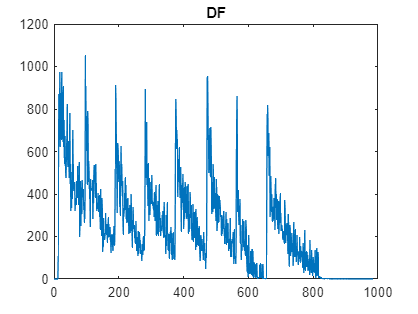

plot(DF)
title('DF')

%Παρατηρουμε πως υπαρχει ιδιος αριθμος peaks αλλα με μεγαλο μεγεθος θορυβου

%Erwtima C.b
for f=1:rows1
    for k=1:cols1
         if k==1
                 dF1=0;
         else if k==2
                dF1(f,k)=wrapToPi(2*XFphase(f,k-1));
         else
            dF1(f,k)=wrapToPi(2*XFphase(f,k-1)-XFphase(f, k-2));
         end
         end
    end
end
dF1

dF1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 


for f=1:rows1
    for k=1:cols1
         if k==1
           dC(f,k)=XF(f,k);
         else
           dC(f,k)=XF(f,k)-XFmag(f,k-1)*exp(1i*dF1(f,k));
         end
    end
end
dC

dC =   -0.0022 + 0.0000i  -0.0042 + 0.0000i  -0.0040 + 0.0000i  -0.0037 + 0.0000i  -0.0038 + 0.0000i  -0.0039 + 0.0000i  -0.0039 + 0.0000i  -0.0039 + 0.0000i  -0.0039 + 0.0000i  -0.0039 + 0.0000i  -0.0038 + 0.0000i  -0.1077 + 0.0000i  -0.1714 + 0.0000i   0.1008 + 0.0000i  -0.2720 + 0.0000i   0.1511 + 0.0000i   0.0987 + 0.0000i  -0.4086 + 0.0000i  -0.0228 + 0.0000i   0.2624 + 0.0000i   0.0243 + 0.0000i  -0.3110 + 0.0000i  -0.0122 + 0.0000i  -0.2399 + 0.0000i  -0.4930 + 0.0000i  -0.2643 + 0.0000i   0.2356 + 0.0000i  -0.2930 + 0.0000i  -0.1689 + 0.0000i  -0.1467 + 0.0000i   0.0560 + 0.0000i  -0.0544 + 0.0000i  -0.1116 + 0.0000i   0.0975 + 0.0000i  -0.0228 + 0.0000i  -0.1685 + 0.0000i  -0.0329 + 0.0000i  -0.0373 + 0.0000i   0.0171 + 0.0000i   0.1541 + 0.0000i  -0.1605 + 0.0000i  -0.0340 + 0.0000i  -0.1029 + 0.0000i  -0.1097 + 0.0000i   0.1574 + 0.0000i  -0.0038 + 0.0000i  -0.0952 + 0.0000i  -0.1463 + 0.0000i  -0.0970 + 0.0000i   0.0223 + 0.0000i
   0.0011 - 0.0000i   0.0000 + 0.0001i  -0.0


DC=sum(abs(dC).^2);
DC

DC = 1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0210    0.1762    0.4112    0.6646    1.0211    1.1558    1.1535    1.1467    1.0852    1.0767    1.0687    1.0537    0.9770    0.8510    0.7946    0.7927    0.8746    0.9203    0.9625    0.9731    0.9639    0.9322    0.9016    0.8301    0.8282    0.8108    0.8150    0.7833    0.7993    0.7944    0.8104    0.7455    0.6952    0.6518    0.6153    0.5741    0.5867    0.5856


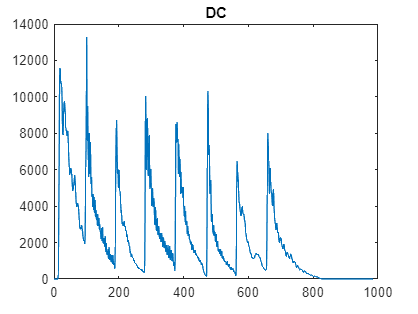

plot(DC)
title('DC')

%Υπαρχει ομοιοτητα με την προηγουμενη κυματομορφη, με μικροτερο επιπεδο
%θορυβου

%Erwtima D

%Στην DE ο εντοπισμός των onset της κάθε νότας είναι ευκολότερος, και αυτή
%εχει το χαμηλοτερο επιπεδο θορυβου σε συγκριση με τις αλλες δυο 
%κυματομορφες. Δευτερη καλύτερη ειναι η DC, ενω χειροτερη
%απο τις τρεις ειναι η DF που παρουσιαζει το μεγαλυτερο επιπεδο
%θορυβου.


%Askisi 3
clc; clear;

[x, Fs]=audioread('piano.wav');
%soundsc(x, Fs)
ovrlp=0.25;
X=frame_wind(x, 512, ovrlp);

XF=fft(X);

XFmag=abs(XF);
XFphase=imag(XF);

[rows, cols]=size(XFmag);
[rows1, cols1]=size(XFphase);
for f=1:rows
    for k=1:cols
        if k==1
            dE(f,k)=XFmag(f,k);
        else
            dE(f,k)=XFmag(f,k)-XFmag(f, k-1);
        end
    end
end
dE;

for f=1:rows
    DE=abs(sum(dE));
end
DE

DE =     0.1903    0.0037    0.0028    0.0079    0.0037    0.0049    0.0004    0.0013    0.0035    0.0145    0.0062    8.8711  152.0900  266.2648  100.4020   46.4536   18.4498   16.3818    7.4273   32.9925    5.2084    5.7508   21.0371   11.2295   16.3901   27.9308   27.2983    1.0662    9.8529    3.2557    6.8639    4.7504    6.2387    4.9631    3.5458    3.1967   11.0501   13.6854   17.7246   17.7726   10.4263    7.5764    2.0776    2.7643    5.5061    9.6626   11.2943    4.0857    4.6910    5.3810


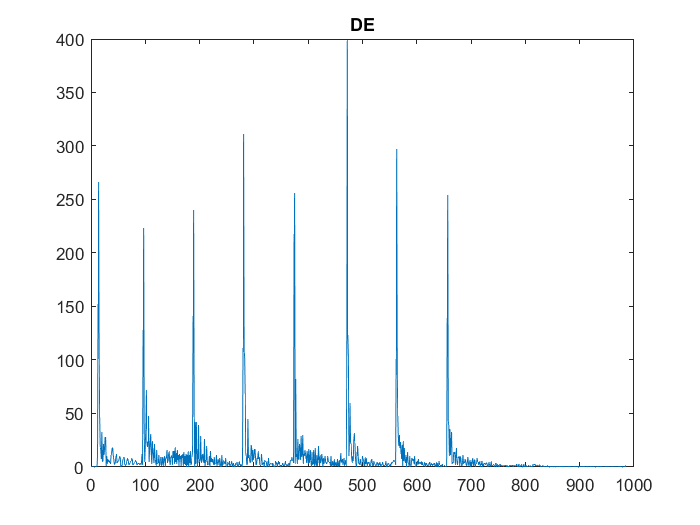

plot(DE)
title('DE');


RDE=xcorr(DE) %αυτοσυσχετιση

RDE = 	1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0019    0.0033    0.0015    0.0010    0.0006    0.0006    0.0009    0.0017    0.0011    0.0012    0.0017    0.0016    0.0014    0.0016    0.0015    0.0010    0.0014    0.0013    0.0013    0.0013    0.0015    0.0011    0.0014    0.0016    0.0018    0.0016    0.0016    0.0017    0.0015    0.0020    0.0017    0.0019    0.0022    0.0024    0.0017    0.0020


NDE=length(DE)

NDE = 986

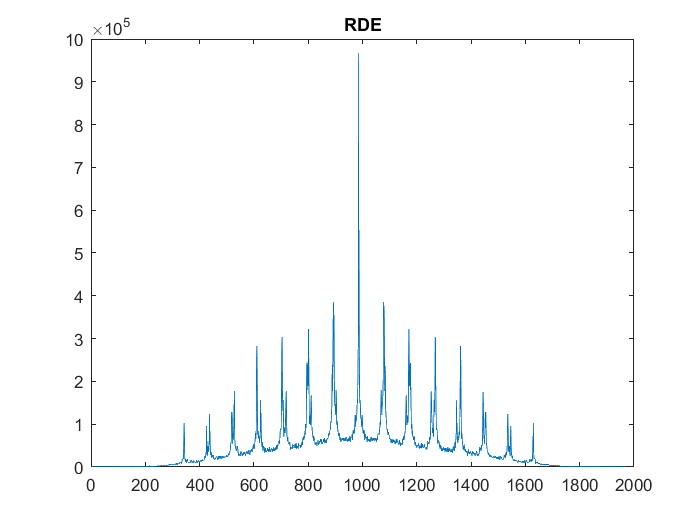


plot(RDE)
title('RDE')


%erwtima b
[pks,locs]=findpeaks(RDE)

pks = 	1.0e+05 *

    0.0000    0.0000    0.0000    0.0000    0.0033    0.0017    0.0017    0.0016    0.0014    0.0015    0.0018    0.0017    0.0020    0.0024    0.0026    0.0019    0.0020    0.0034    0.0024    0.0029    0.0027    0.0037    0.0027    0.0031    0.0038    0.0028    0.0036    0.0047    0.0066    0.0061    0.0063    0.0071    0.0058    0.0067    0.0061    0.0066    0.0067    0.0071    0.0070    0.0071    0.0068    0.0065    0.0081    0.0081    0.0073    0.0095    0.0092    0.0085    0.0119    0.0149


locs =      3     5     9    12    16    22    25    28    31    35    39    42    44    48    51    55    57    61    64    70    74    79    83    85    88    91    94    96    99   105   108   115   118   121   125   128   130   134   136   138   140   145   149   153   155   159   161   165   168   174


p=maxk(pks, 2)

p = 	1.0e+05 *

    9.6671    3.8504


A1=find(pks==min(p),1,"last") %κελι στον πινακα pks

A1 = 272

A2=find(pks==max(p)) %κελι στον πινακα pks

A2 = 246


B1=locs(1,A1) %θεση δευτερης μεγαλυτερης κορυφης

B1 = 1078

B2=locs(1,A2) %θεση μεγαλυτερης κορυφη

B2 = 986


distance=abs(B2-B1) %το αποτελεσμα ειναι δειγματα

distance = 92


%erwtima c

SDE=distance*512*ovrlp   %δείγματα

SDE = 11776


seconds=SDE/Fs*1

seconds = 0.7360


bpm=60/seconds

bpm = 81.5217

%askisi 3 erwtima d (me pinaka DF)
clc; clear;

[x, Fs]=audioread('piano.wav');
%soundsc(x, Fs)
ovrlp=0.25;
X=frame_wind(x, 512, ovrlp);

XF=fft(X);

XFmag=abs(XF);
XFphase=imag(XF);

[rows1, cols1]=size(XFphase);

for f=1:rows1
    for k=1:cols1
        if k==2
            dF(f,k)=wrapToPi(XFphase(f,k))-wrapToPi(2*XFphase(f,k-1));
        else if k==1
                dF(f,k)=wrapToPi(XFphase(f,k));
        else
            dF(f,k)=wrapToPi(XFphase(f,k))-wrapToPi(2*XFphase(f,k-1)-XFphase(f, k-2));
        end
        end
    end
end
dF;

DF=sum(abs(dF).^2);
DF

DF = 	1.0e+03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.1071    0.5287    0.8682    0.6781    0.6818    0.9741    0.6224    0.8610    0.7254    0.8741    0.6561    0.9725    0.6612    0.8265    0.6746    0.6458    0.9064    0.6218    0.7489    0.5663    0.5438    0.6718    0.5312    0.5106    0.4737    0.5644    0.6193    0.6782    0.8228    0.5856    0.5268    0.6505    0.6004    0.5624    0.4747    0.6398    0.7819    0.4468


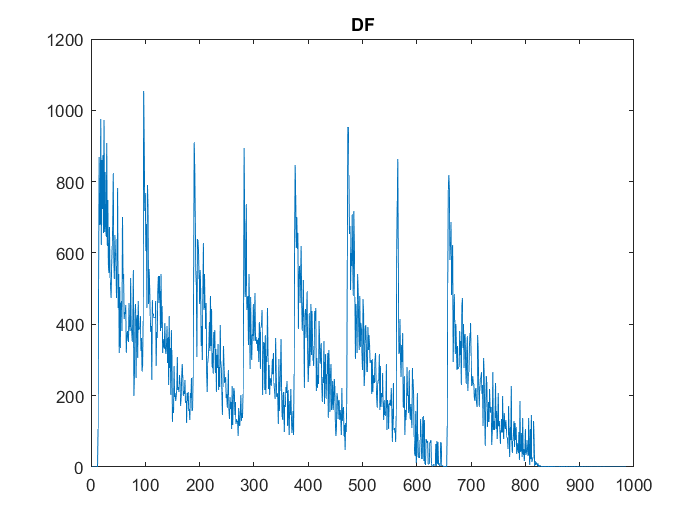

plot(DF)
title('DF')


RDF=xcorr(DF)

RDF = 	1.0e+08 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


NDF=length(DF)

NDF = 986

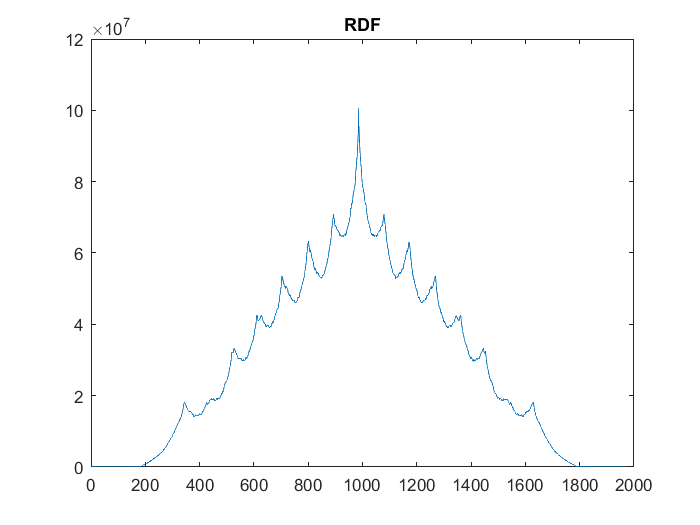


plot(RDF)
title('RDF')


[pks,locs]=findpeaks(RDF)

pks = 	1.0e+08 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0004    0.0028    0.0072    0.0093    0.0101    0.0109    0.0137    0.0178    0.0214    0.0238    0.0319    0.0428    0.0492    0.0508    0.1812    0.1791    0.1647    0.1576    0.1567    0.1564    0.1542    0.1479    0.1426    0.1449    0.1468    0.1446    0.1440    0.1453    0.1482    0.1485    0.1494    0.1486    0.1548    0.1808    0.1889    0.1915    0.1904    0.1911


locs =      8    37    69    71    79   106   130   135   140   142   145   149   164   186   195   201   204   206   211   220   227   232   246   261   268   270   344   346   354   360   365   367   369   375   381   384   387   390   392   395   398   400   402   405   411   426   438   443   447   452


p=maxk(pks, 2)

p = 	1.0e+08 *

    1.0053    0.7380


A1=find(pks==min(p),1,"last") %κελι στον πινακα pks

A1 = 120

A2=find(pks==max(p)) %κελι στον πινακα pks

A2 = 119


B1=locs(1,A1) %θεση δευτερης μεγαλυτερης κορυφης

B1 = 1012

B2=locs(1,A2) %θεση μεγαλυτερης κορυφη

B2 = 986


distance=abs(B2-B1)

distance = 26


SDF=distance*512*ovrlp

SDF = 3328


seconds=SDF/Fs*1

seconds = 0.2080


bpm=60/seconds

bpm = 288.4615

%(me pinaka DC)
clc; clear;

[x, Fs]=audioread('piano.wav');
%soundsc(x, Fs)
ovrlp=0.25;
X=frame_wind(x, 512, ovrlp);

XF=fft(X);

XFmag=abs(XF);
XFphase=imag(XF);

[rows, cols]=size(XFmag);
[rows1, cols1]=size(XFphase);

for f=1:rows
    for k=1:cols
         if k==1
                 dF1=0;
         else if k==2
                dF1(f,k)=wrapToPi(2*XFphase(f,k-1));
         else
            dF1(f,k)=wrapToPi(2*XFphase(f,k-1)-XFphase(f, k-2));
         end
         end
    end
end
dF1

dF1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 


for f=1:rows
    for k=1:cols
         if k==1
           dC(f,k)=XF(f,k);
         else
           dC(f,k)=XF(f,k)-XFmag(f,k-1)*exp(1i*dF1(f,k));
         end
    end
end
dC

dC =   -0.0022 + 0.0000i  -0.0042 + 0.0000i  -0.0040 + 0.0000i  -0.0037 + 0.0000i  -0.0038 + 0.0000i  -0.0039 + 0.0000i  -0.0039 + 0.0000i  -0.0039 + 0.0000i  -0.0039 + 0.0000i  -0.0039 + 0.0000i  -0.0038 + 0.0000i  -0.1077 + 0.0000i  -0.1714 + 0.0000i   0.1008 + 0.0000i  -0.2720 + 0.0000i   0.1511 + 0.0000i   0.0987 + 0.0000i  -0.4086 + 0.0000i  -0.0228 + 0.0000i   0.2624 + 0.0000i   0.0243 + 0.0000i  -0.3110 + 0.0000i  -0.0122 + 0.0000i  -0.2399 + 0.0000i  -0.4930 + 0.0000i  -0.2643 + 0.0000i   0.2356 + 0.0000i  -0.2930 + 0.0000i  -0.1689 + 0.0000i  -0.1467 + 0.0000i   0.0560 + 0.0000i  -0.0544 + 0.0000i  -0.1116 + 0.0000i   0.0975 + 0.0000i  -0.0228 + 0.0000i  -0.1685 + 0.0000i  -0.0329 + 0.0000i  -0.0373 + 0.0000i   0.0171 + 0.0000i   0.1541 + 0.0000i  -0.1605 + 0.0000i  -0.0340 + 0.0000i  -0.1029 + 0.0000i  -0.1097 + 0.0000i   0.1574 + 0.0000i  -0.0038 + 0.0000i  -0.0952 + 0.0000i  -0.1463 + 0.0000i  -0.0970 + 0.0000i   0.0223 + 0.0000i
   0.0011 - 0.0000i   0.0000 + 0.0001i  -0.0


DC=sum(abs(dC).^2);
DC

DC = 	1.0e+04 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0210    0.1762    0.4112    0.6646    1.0211    1.1558    1.1535    1.1467    1.0852    1.0767    1.0687    1.0537    0.9770    0.8510    0.7946    0.7927    0.8746    0.9203    0.9625    0.9731    0.9639    0.9322    0.9016    0.8301    0.8282    0.8108    0.8150    0.7833    0.7993    0.7944    0.8104    0.7455    0.6952    0.6518    0.6153    0.5741    0.5867    0.5856


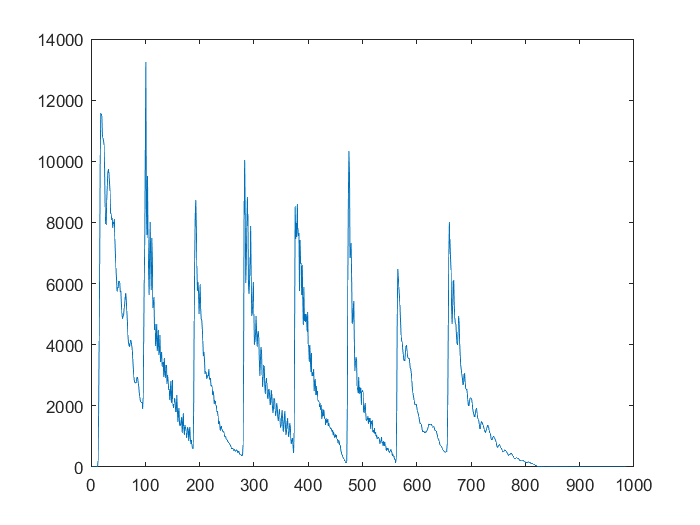

plot(DC)

title('DC')

RDC=xcorr(DC)

RDC = 	1.0e+10 *

         0   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


NDC=length(DC) 

NDC = 986

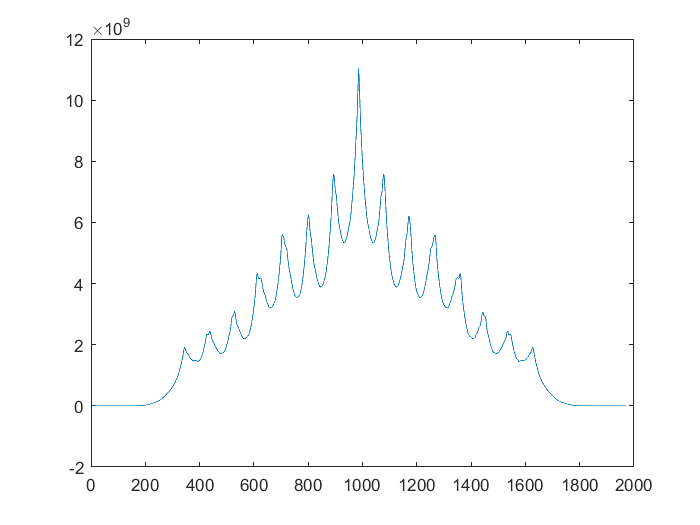


plot(RDC)

title('RDC')

[pks,locs]=findpeaks(RDC)

pks = 	1.0e+10 *

    0.0001    0.1902    0.1488    0.1477    0.2346    0.2444    0.2940    0.3077    0.4329    0.4193    0.3217    0.5600    0.6220    0.7582    1.1043    0.7582    0.6220    0.5600    0.3217    0.4193    0.4329    0.3077    0.2940    0.2444    0.2346    0.1477    0.1488    0.1902    0.0001


locs =          161         345         378         387         427         438         522         529         612         623         661         705         801         894         986        1078        1171        1267        1311        1349        1360        1443        1450        1534        1545        1585        1594        1627        1811


p=maxk(pks, 2)

p = 	1.0e+10 *

    1.1043    0.7582


A1=find(pks==min(p),1,"last")%κελι στον πινακα pks

A1 = 16

A2=find(pks==max(p))%κελι στον πινακα pks

A2 = 15


B1=locs(1,A1)%θεση δευτερης μεγαλυτερης κορυφης

B1 = 1078

B2=locs(1,A2)%θεση μεγαλυτερης κορυφης

B2 = 986


distance=abs(B2-B1)

distance = 92


SDC=distance*512*ovrlp

SDC = 11776


seconds=SDC/Fs*1

seconds = 0.7360


bpm=60/seconds

bpm = 81.5217


%Αφού δοκιμάσαμε και τις 3 κυματομορφές παρατηρούμε ότι οι δύο από αυτές
%έχουν την μεγαλύτερη ακρίβεια. Αυτές είναι οι DE και η DC αφού βγάζουν
%bpm=81.5217 το οποίο είναι πολύ κοντά στα 80 bpm που μας δίνεται ως
%δεδομένο για το συγκεκριμένο κομμάτι. Η κυματομορφή DF δεν μπορεί να
%χρησιμοποιηθεί, διότι τα bpm που βγάζει ξεπερνούν κατά πολύ τα bpm του
%κομματιού που μας δίνονται.

%askisi 3 erwtima e
%me pinaka DE

clc; clear;
[x, Fs]=audioread('insomnia.wav');
%soundsc(x, Fs)
ovrlp=0.25;
X=frame_wind(x, 512, ovrlp);

XF=fft(X);

XFmag=abs(XF);
XFphase=imag(XF);

[rows, cols]=size(XFmag);

for f=1:rows
    for k=1:cols
        if k==1
            dE(f,k)=XFmag(f,k);
        else
            dE(f,k)=XFmag(f,k)-XFmag(f, k-1);
        end
    end
end
dE;

for f=1:rows
    DE=abs(sum(dE));
end
DE

DE =   607.8147   24.1762   36.1016    8.7039   76.4223  525.8611  176.4972  229.2306   13.9139  175.5347  129.7624  152.5401   21.1150   87.5788   39.4550   76.5185   38.2265   55.4766   29.6283   25.0809   12.2011    1.4136  121.6332   53.5821   40.8306   16.1973    1.8089   42.6273   47.0717   18.0127   47.8184    1.0592   94.8756  172.7236  250.2525  377.8718   55.9964   70.3067   47.9205   27.7278   69.8609   66.4786   29.1723   81.3431   10.1642   23.5753   76.3977   94.8118   35.0890   20.7718


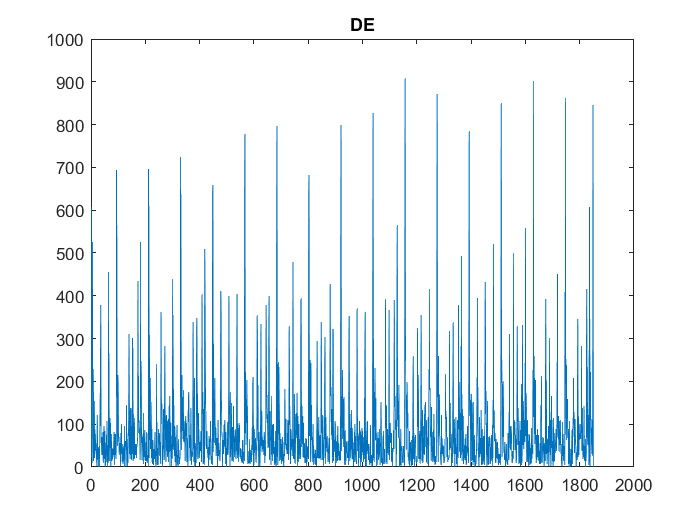

plot(DE)
title('DE')


RDE=xcorr(DE)

RDE = 	1.0e+07 *

   -0.0000         0    0.0514    0.0036    0.0098    0.0066    0.0090    0.0484    0.0209    0.0335    0.0160    0.0352    0.0261    0.0220    0.0358    0.0596    0.0431    0.0265    0.0262    0.0444    0.0589    0.0481    0.0340    0.0395    0.0445    0.0634    0.0480    0.0295    0.0323    0.0361    0.0487    0.0417    0.0396    0.0263    0.0353    0.0441    0.0504    0.0609    0.0356    0.0328    0.0408    0.0286    0.0360    0.0347    0.0415    0.0609    0.0400    0.0474    0.0542    0.0726


NDE=length(DE)

NDE = 1851

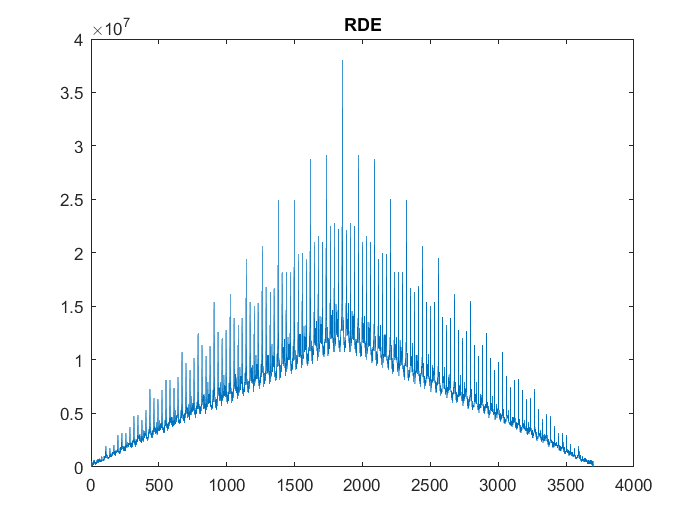


plot(RDE)
title('RDE')


[pks,locs]=findpeaks(RDE)

pks = 	1.0e+07 *

    0.0514    0.0098    0.0484    0.0335    0.0352    0.0596    0.0589    0.0634    0.0487    0.0609    0.0408    0.0360    0.0609    0.0734    0.0794    0.0658    0.0543    0.0779    0.0539    0.0661    0.0653    0.1014    0.0636    0.0670    0.0696    0.0627    0.1059    0.0802    0.1511    0.1934    0.1163    0.1110    0.0871    0.0875    0.0850    0.1128    0.1724    0.1156    0.1070    0.1044    0.1237    0.1353    0.1395    0.2074    0.1235    0.1496    0.1464    0.1224    0.1291    0.1568


locs =      3     5     8    10    12    16    21    26    31    38    41    43    46    51    59    61    64    67    70    74    76    80    84    89    91    94    96   100   105   110   114   120   123   127   130   134   139   145   147   150   153   156   163   169   173   175   177   180   182   185


p=maxk(pks, 2)

p = 	1.0e+07 *

    3.8049    2.9176


A1=find(pks==min(p),1,"last") %κελι στον πινακα pks

A1 = 523

A2=find(pks==max(p)) %κελι στον πινακα pks

A2 = 495


B1=locs(1,A1) %θεση δευτερης μεγαλυτερης κορυφης

B1 = 1969

B2=locs(1,A2) %θεση μεγαλυτερης κορυφη

B2 = 1851


distance=abs(B2-B1)

distance = 118


SDE=distance*512*ovrlp

SDE = 15104


seconds=SDE/Fs*1

seconds = 0.9440


bpm=60/seconds

bpm = 63.5593

%erwtima e 
%(me pinaka DF)
clc; clear;

[x, Fs]=audioread('insomnia.wav');
%soundsc(x, Fs)
ovrlp=0.25;
X=frame_wind(x, 512, ovrlp);

XF=fft(X);

XFmag=abs(XF);
XFphase=imag(XF);

[rows, cols]=size(XFmag);

for f=1:rows
    for k=1:cols
        if k==2
            dF(f,k)=wrapToPi(XFphase(f,k))-wrapToPi(2*XFphase(f,k-1));
        else if k==1
                dF(f,k)=wrapToPi(XFphase(f,k));
        else
            dF(f,k)=wrapToPi(XFphase(f,k))-wrapToPi(2*XFphase(f,k-1)-XFphase(f, k-2));
        end
        end
    end
end
dF;

DF=sum(abs(dF).^2);
DF

DF = 	1.0e+03 *

    0.3712    0.8199    0.8927    0.7463    0.7808    1.4715    1.8513    2.0000    1.7973    1.7332    1.4674    1.3156    1.3478    1.6348    1.1377    0.9481    0.8293    1.0013    0.9761    1.0272    0.8502    0.9307    0.7675    1.0429    0.7908    0.8378    0.8562    0.8669    0.8035    0.7632    0.6276    0.7173    0.6951    0.6777    1.3166    1.7148    1.7661    2.2125    1.6599    1.4963    1.2705    1.4015    1.1252    1.0139    1.1461    1.0250    1.4692    1.2049    1.2789    0.9860


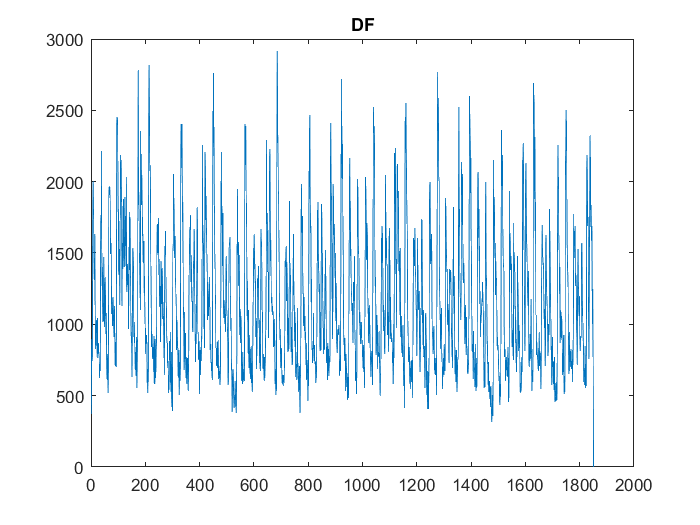

plot(DF)
title('DF')


RDF=xcorr(DF)

RDF = 	1.0e+09 *

   -0.0000    0.0002    0.0007    0.0015    0.0024    0.0033    0.0048    0.0068    0.0093    0.0118    0.0144    0.0173    0.0203    0.0233    0.0263    0.0288    0.0311    0.0327    0.0346    0.0363    0.0379    0.0389    0.0396    0.0400    0.0413    0.0431    0.0449    0.0456    0.0466    0.0477    0.0489    0.0494    0.0494    0.0487    0.0479    0.0471    0.0474    0.0484    0.0497    0.0505    0.0520    0.0537    0.0558    0.0583    0.0607    0.0630    0.0654    0.0680    0.0706    0.0727


NDF=length(DF)

NDF = 1851

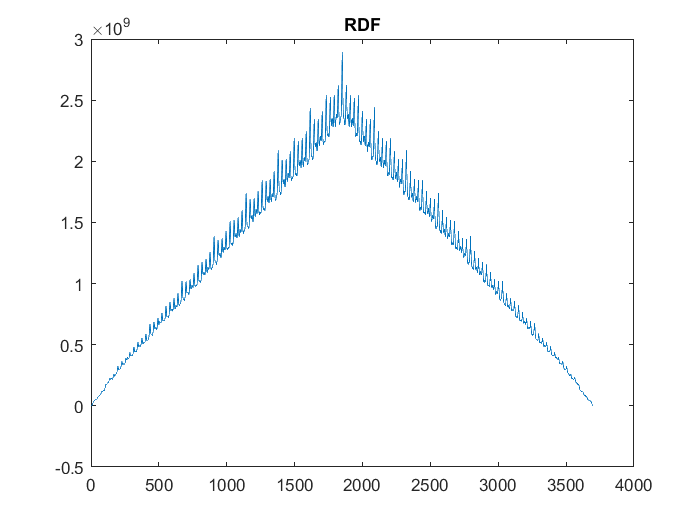


plot(RDF)
title('RDF')


[pks,locs]=findpeaks(RDF)

pks = 	1.0e+09 *

    0.0494    0.0871    0.1197    0.1244    0.1763    0.1878    0.2303    0.2227    0.2594    0.3233    0.2999    0.3629    0.3465    0.3465    0.3935    0.3946    0.4366    0.4129    0.4836    0.4497    0.5202    0.4953    0.5539    0.5230    0.5885    0.5360    0.5374    0.6722    0.5854    0.5842    0.6868    0.6416    0.7165    0.6895    0.7632    0.6976    0.6977    0.8176    0.7314    0.8511    0.7904    0.8793    0.8214    0.8107    0.9198    0.8332    1.0208    0.8728    1.0168    0.9336


locs =     32    62    80    93   110   124   139   153   169   198   211   228   240   242   257   271   287   298   316   329   346   359   375   390   404   413   416   434   445   448   464   477   493   508   523   534   537   552   566   582   596   611   626   631   641   656   670   683   700   714


p=maxk(pks, 2)

p = 	1.0e+09 *

    2.8904    2.6208


A1=find(pks==min(p),1,"last") %κελι στον πινακα pks

A1 = 126

A2=find(pks==max(p)) %κελι στον πινακα pks

A2 = 125


B1=locs(1,A1) %θεση δευτερης μεγαλυτερης κορυφης

B1 = 1881

B2=locs(1,A2) %θεση μεγαλυτερης κορυφη

B2 = 1851


distance=abs(B2-B1)

distance = 30


SDF=distance*512*ovrlp

SDF = 3840


seconds=SDF/Fs*1

seconds = 0.2400


bpm=60/seconds

bpm = 250

[x, Fs]=audioread('insomnia.wav');
%soundsc(x, Fs)
ovrlp=0.25;
X=frame_wind(x, 512, ovrlp);

XF=fft(X);

XFmag=abs(XF);
XFphase=imag(XF);

[rows, cols]=size(XFmag);

for f=1:rows
    for k=1:cols
         if k==1
                 dF1=0;
         else if k==2
                dF1(f,k)=wrapToPi(2*XFphase(f,k-1));
         else
            dF1(f,k)=wrapToPi(2*XFphase(f,k-1)-XFphase(f, k-2));
         end
         end
    end
end
dF1

dF1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 


for f=1:rows
    for k=1:cols
         if k==1
           dC(f,k)=XF(f,k);
         else
           dC(f,k)=XF(f,k)-XFmag(f,k-1)*exp(1i*dF1(f,k));
         end
    end
end
dC

dC = 	1.0e+02 *

   0.0061 + 0.0000i  -0.0057 + 0.0000i  -0.0003 + 0.0000i   0.0024 + 0.0000i  -0.0038 + 0.0000i  -0.0055 + 0.0000i  -0.0025 + 0.0000i   0.0031 + 0.0000i  -0.0050 + 0.0000i   0.0005 + 0.0000i  -0.0018 + 0.0000i  -0.0052 + 0.0000i  -0.0063 + 0.0000i  -0.0042 + 0.0000i  -0.0033 + 0.0000i  -0.0036 + 0.0000i  -0.0052 + 0.0000i  -0.0051 + 0.0000i  -0.0036 + 0.0000i  -0.0033 + 0.0000i  -0.0061 + 0.0000i  -0.0104 + 0.0000i  -0.0144 + 0.0000i  -0.0013 + 0.0000i  -0.0098 + 0.0000i  -0.0082 + 0.0000i   0.0015 + 0.0000i  -0.0167 + 0.0000i  -0.0080 + 0.0000i   0.0066 + 0.0000i  -0.0112 + 0.0000i  -0.0002 + 0.0000i  -0.0019 + 0.0000i  -0.0070 + 0.0000i  -0.0031 + 0.0000i  -0.0037 + 0.0000i   0.0061 + 0.0000i  -0.0061 + 0.0000i   0.0451 + 0.0000i  -0.0872 + 0.0000i  -0.0606 + 0.0000i  -0.0370 + 0.0000i   0.0608 + 0.0000i  -0.0396 + 0.0000i  -0.0205 + 0.0000i  -0.0335 + 0.0000i  -0.0553 + 0.0000i   0.0506 + 0.0000i  -0.2039 + 0.0000i  -0.0599 + 0.0000i
  -0.0046 - 0.0023i  -0.0067 - 0


DC=sum(abs(dC).^2);
DC

DC = 	1.0e+04 *

    0.3261    0.7247    0.7435    0.8057    0.7525    1.2549    2.2505    2.5223    2.1507    2.0982    1.4897    0.8257    0.7620    0.7190    0.6424    0.5792    0.4421    0.4359    0.4189    0.4583    0.5449    0.4691    0.5797    0.7688    0.6227    0.5118    0.5769    0.4942    0.4902    0.3087    0.2807    0.3542    0.3112    0.2812    0.5606    1.5267    2.7659    3.1231    3.2582    4.0806    4.8847    5.7236    4.2331    4.4475    2.9888    2.8784    2.8471    1.2075    1.8341    0.8553


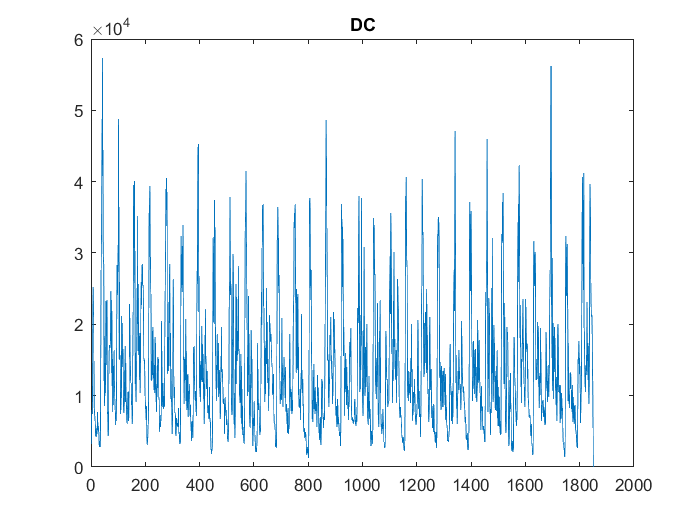

plot(DC)
title('DC')


RDC=xcorr(DC)

RDC = 	1.0e+11 *

   -0.0000   -0.0000    0.0002    0.0008    0.0017    0.0029    0.0044    0.0063    0.0091    0.0127    0.0169    0.0219    0.0273    0.0320    0.0361    0.0392    0.0416    0.0443    0.0473    0.0500    0.0509    0.0491    0.0457    0.0421    0.0397    0.0393    0.0397    0.0407    0.0419    0.0429    0.0442    0.0448    0.0449    0.0456    0.0459    0.0459    0.0470    0.0488    0.0520    0.0573    0.0636    0.0737    0.0864    0.0993    0.1115    0.1235    0.1352    0.1473    0.1585    0.1656


NDC=length(DC) 

NDC = 1851

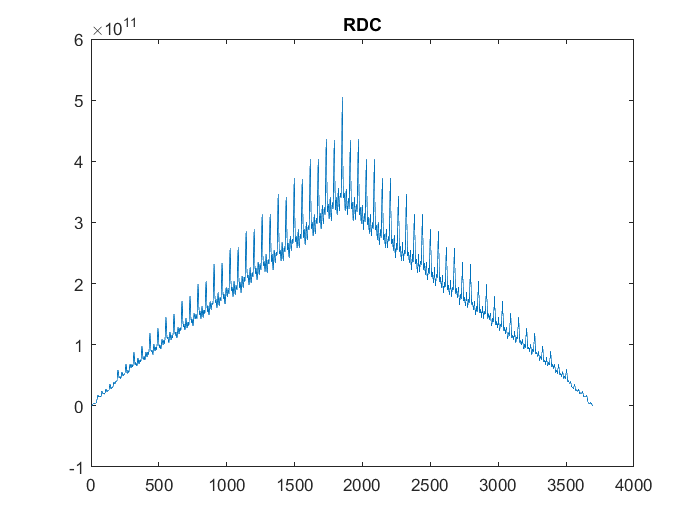


plot(RDC)
title('RDC')


[pks,locs]=findpeaks(RDC)

pks = 	1.0e+11 *

    0.0509    0.1705    0.1571    0.1470    0.2378    0.2112    0.2753    0.2609    0.3528    0.3076    0.3928    0.4085    0.5908    0.4582    0.4812    0.5551    0.5226    0.5209    0.5138    0.6817    0.5780    0.6794    0.6778    0.6371    0.8859    0.7037    0.7067    0.7889    0.7490    0.9801    0.8099    0.8821    0.8752    0.8465    1.1934    0.8912    0.9168    1.0078    0.9634    1.2662    0.9574    1.0022    1.0856    1.0670    1.0734    1.4481    1.1287    1.2117    1.1496    1.1125


locs =     21    52    65    70    82    95   111   127   139   156   170   184   198   208   213   228   243   245   247   257   272   288   301   306   316   329   331   346   361   375   390   406   420   424   434   444   449   464   478   493   503   508   523   535   537   552   565   582   596   601


p=maxk(pks, 2)

p = 	1.0e+11 *

    5.0529    4.3583


A1=find(pks==min(p),1,"last") %κελι στον πινακα pks

A1 = 171

A2=find(pks==max(p)) %κελι στον πινακα pks

A2 = 160


B1=locs(1,A1) %θεση δευτερης μεγαλυτερης κορυφης

B1 = 1969

B2=locs(1,A2) %θεση μεγαλυτερης κορυφη

B2 = 1851


distance=abs(B2-B1)

distance = 118


SDC=distance*512*ovrlp

SDC = 15104


seconds=SDC/Fs*1

seconds = 0.9440


bpm=60/seconds

bpm = 63.5593


%Αρχικά βρίσκουμε στο διαδίκτυο ότι τα bpm του κομματιού insomnia είναι
%127. Παρατηρούμε ότι κανένα από τα bpm των τριών κυματομορφών δεν είναι
%αρκετά κοντά στα 127 bpm, αφού οι δύο βγάζουν 63.5593 bpm και η άλλη 250
%bpm.Αν μπορούσαμε να πούμε ότι κάποιες έχουν μεγαλύτερη ακρίβεια αυτές θα
%ήταν οι DC και η DE με τα 63.5593 bpm.

%erwtima e
%me pinaka DE

clc; clear;
[x, Fs]=audioread('seven_nation_army.wav');
%soundsc(x, Fs)
ovrlp=0.25;
X=frame_wind(x, 512, ovrlp);

XF=fft(X);

XFmag=abs(XF);
XFphase=imag(XF);

[rows, cols]=size(XFmag);

for f=1:rows
    for k=1:cols
        if k==1
            dE(f,k)=XFmag(f,k);
        else
            dE(f,k)=XFmag(f,k)-XFmag(f, k-1);
        end
    end
end
dE;

for f=1:rows
    DE=abs(sum(dE));
end
DE

DE =   163.0072    7.6045   21.9961   10.9293    7.9973    0.7840   30.5029   26.5647   51.3525    2.0229    0.3830    9.9461    7.9580   14.3130   37.8626    8.3531   10.2999   10.5554   16.4986    0.2156    7.9063   11.7463    0.5624    4.4608    1.6494    3.3112    7.7180    6.2583   15.2399   15.2250    9.5462   15.1584    0.9629   17.5871   98.0713  189.7844  122.1490  379.8006  260.8807  331.3133  102.4394  106.3662   90.7946   74.3158   24.3829   21.9434   39.7711   23.6245   26.0170   28.2280


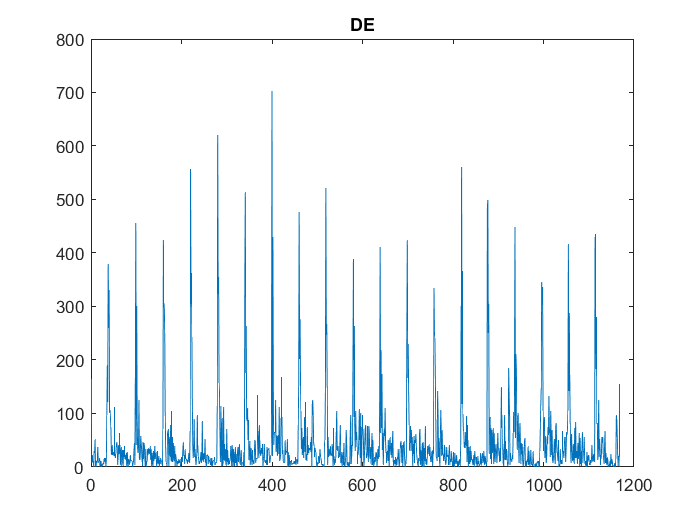

plot(DE)
title('DE')


RDE=xcorr(DE)

RDE = 	1.0e+07 *

    0.0000         0    0.0025    0.0005    0.0007    0.0003    0.0006    0.0010    0.0020    0.0023    0.0015    0.0006    0.0005    0.0006    0.0007    0.0011    0.0014    0.0009    0.0006    0.0007    0.0008    0.0010    0.0008    0.0010    0.0005    0.0006    0.0005    0.0005    0.0007    0.0008    0.0006    0.0007    0.0009    0.0007    0.0016    0.0015    0.0024    0.0042    0.0035    0.0080    0.0069    0.0091    0.0065    0.0077    0.0082    0.0098    0.0107    0.0090    0.0094    0.0059


NDE=length(DE)

NDE = 1170

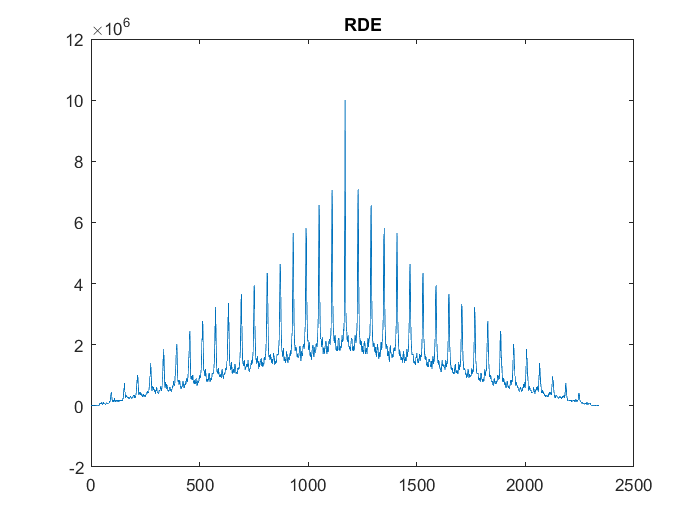


plot(RDE)
title('RDE')


[pks,locs]=findpeaks(RDE)

pks = 	1.0e+07 *

    0.0025    0.0007    0.0023    0.0014    0.0010    0.0010    0.0006    0.0008    0.0009    0.0016    0.0042    0.0080    0.0091    0.0107    0.0094    0.0051    0.0090    0.0122    0.0071    0.0079    0.0094    0.0089    0.0097    0.0096    0.0143    0.0425    0.0186    0.0176    0.0226    0.0168    0.0199    0.0188    0.0177    0.0169    0.0180    0.0180    0.0181    0.0190    0.0187    0.0252    0.0738    0.0456    0.0353    0.0305    0.0289    0.0295    0.0292    0.0265    0.0321    0.0263


locs =      3     5    10    17    22    24    26    30    33    35    38    40    42    47    49    52    54    57    60    64    72    75    78    81    86    93   101   103   108   114   116   120   122   127   129   133   137   139   144   147   154   157   162   165   167   169   173   175   181   186


p=maxk(pks, 2)

p = 	1.0e+07 *

    1.0012    0.7074


A1=find(pks==min(p),1,"last") %κελι στον πινακα pks

A1 = 278

A2=find(pks==max(p)) %κελι στον πινακα pks

A2 = 266


B1=locs(1,A1) %θεση δευτερης μεγαλυτερης κορυφης

B1 = 1230

B2=locs(1,A2) %θεση μεγαλυτερης κορυφη

B2 = 1170


distance=abs(B2-B1)

distance = 60


SDE=distance*512*ovrlp

SDE = 7680


seconds=SDE/Fs*1

seconds = 0.4800


bpm=60/seconds

bpm = 125

%(me pinaka DF)
clc; clear;

[x, Fs]=audioread('seven_nation_army.wav');
%soundsc(x, Fs)
ovrlp=0.25;
X=frame_wind(x, 512, ovrlp);

XF=fft(X);

XFmag=abs(XF);
XFphase=imag(XF);

[rows, cols]=size(XFmag);

for f=1:rows
    for k=1:cols
        if k==2
            dF(f,k)=wrapToPi(XFphase(f,k))-wrapToPi(2*XFphase(f,k-1));
        else if k==1
                dF(f,k)=wrapToPi(XFphase(f,k));
        else
            dF(f,k)=wrapToPi(XFphase(f,k))-wrapToPi(2*XFphase(f,k-1)-XFphase(f, k-2));
        end
        end
    end
end
dF;

DF=sum(abs(dF).^2);
DF

DF = 	1.0e+03 *

    0.0651    0.1554    0.2616    0.2119    0.2102    0.2346    0.2727    0.1395    0.2555    0.1294    0.1777    0.1244    0.0907    0.1292    0.0986    0.0566    0.0504    0.0437    0.0936    0.0375    0.0591    0.1205    0.0472    0.0290    0.0915    0.0401    0.0725    0.0352    0.0645    0.0219    0.0565    0.0915    0.0624    0.0441    0.0815    0.3582    0.8465    1.3212    2.0363    1.9461    1.2955    0.9376    0.8304    0.5762    0.6083    0.7463    0.6238    0.5783    0.6481    0.5697


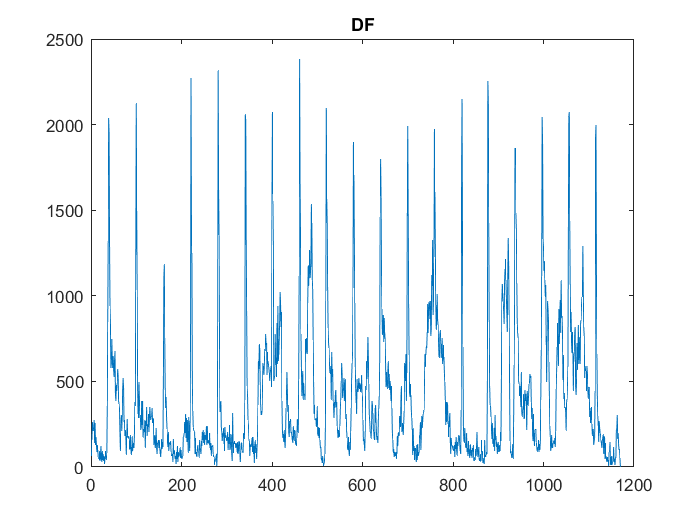

plot(DF)
title('DF')


RDF=xcorr(DF)

RDF = 	1.0e+08 *

   -0.0000    0.0000    0.0001    0.0004    0.0006    0.0009    0.0013    0.0018    0.0023    0.0029    0.0032    0.0034    0.0033    0.0034    0.0031    0.0032    0.0029    0.0029    0.0026    0.0025    0.0023    0.0022    0.0021    0.0021    0.0020    0.0023    0.0024    0.0023    0.0024    0.0025    0.0023    0.0024    0.0022    0.0026    0.0025    0.0027    0.0031    0.0040    0.0052    0.0072    0.0098    0.0127    0.0152    0.0187    0.0217    0.0240    0.0251    0.0242    0.0219    0.0201


NDF=length(RDF)

NDF = 2339

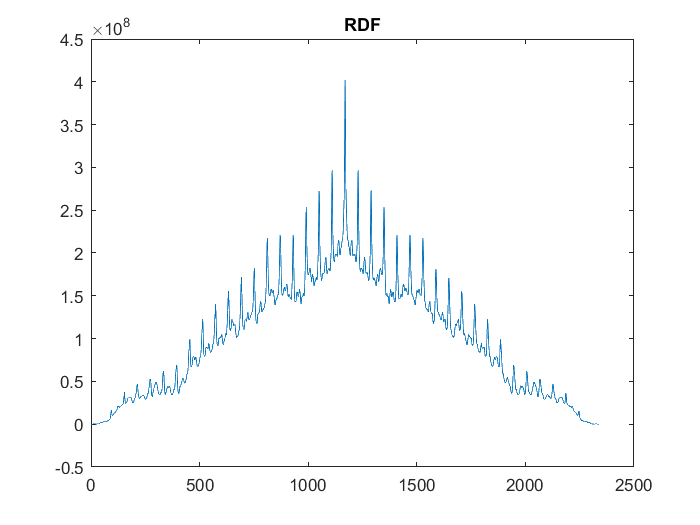


plot(RDF)
title('RDF')


[pks,locs]=findpeaks(RDF)

pks = 	1.0e+08 *

    0.0034    0.0034    0.0032    0.0029    0.0021    0.0024    0.0025    0.0024    0.0026    0.0251    0.0319    0.0334    0.1579    0.1340    0.2151    0.2120    0.2216    0.2220    0.3679    0.2445    0.3167    0.3189    0.3147    0.3151    0.4672    0.3330    0.3403    0.3441    0.5289    0.4919    0.3499    0.3767    0.6157    0.4433    0.4458    0.3458    0.3605    0.4105    0.6919    0.5438    0.9886    0.7912    0.7832    0.6764    0.7916    1.2210    0.8979    0.8982    0.9408    1.3959


locs =     12    14    16    18    24    27    30    32    34    47    58    61    94   108   125   135   140   142   154   161   173   176   180   182   213   231   236   239   273   300   314   322   334   354   361   374   377   383   394   423   455   472   483   491   503   514   530   534   543   574


p=maxk(pks, 2)

p = 	1.0e+08 *

    4.0235    2.9638


A1=find(pks==min(p),1,"last") %κελι στον πινακα pks

A1 = 98

A2=find(pks==max(p)) %κελι στον πινακα pks

A2 = 94


B1=locs(1,A1) %θεση δευτερης μεγαλυτερης κορυφης

B1 = 1230

B2=locs(1,A2) %θεση μεγαλυτερης κορυφη

B2 = 1170


distance=abs(B2-B1)

distance = 60


SDF=distance*512*ovrlp

SDF = 7680


seconds=SDF/Fs*1

seconds = 0.4800


bpm=60/seconds

bpm = 125

[x, Fs]=audioread('seven_nation_army.wav');
%soundsc(x, Fs)
ovrlp=0.25;
X=frame_wind(x, 512, ovrlp);

XF=fft(X);

XFmag=abs(XF);
XFphase=imag(XF);

[rows, cols]=size(XFmag);

for f=1:rows
    for k=1:cols
         if k==1
                 dF1=0;
         else if k==2
                dF1(f,k)=wrapToPi(2*XFphase(f,k-1));
         else
            dF1(f,k)=wrapToPi(2*XFphase(f,k-1)-XFphase(f, k-2));
         end
         end
    end
end
dF1

dF1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 


for f=1:rows
    for k=1:cols
         if k==1
           dC(f,k)=XF(f,k);
         else
           dC(f,k)=XF(f,k)-XFmag(f,k-1)*exp(1i*dF1(f,k));
         end
    end
end
dC

dC = 	1.0e+02 *

  -0.0042 + 0.0000i  -0.0349 + 0.0000i  -0.0262 + 0.0000i   0.0098 + 0.0000i  -0.0260 + 0.0000i  -0.0172 + 0.0000i   0.0124 + 0.0000i  -0.0379 + 0.0000i  -0.0396 + 0.0000i   0.0166 + 0.0000i  -0.0496 + 0.0000i  -0.0438 + 0.0000i   0.0015 + 0.0000i  -0.0493 + 0.0000i  -0.0287 + 0.0000i   0.0136 + 0.0000i  -0.0455 + 0.0000i  -0.0368 + 0.0000i   0.0002 + 0.0000i  -0.0178 + 0.0000i  -0.0216 + 0.0000i  -0.0057 + 0.0000i  -0.0120 + 0.0000i  -0.0251 + 0.0000i  -0.0154 + 0.0000i   0.0008 + 0.0000i  -0.0215 + 0.0000i  -0.0228 + 0.0000i   0.0083 + 0.0000i  -0.0345 + 0.0000i  -0.0277 + 0.0000i   0.0043 + 0.0000i  -0.0258 + 0.0000i  -0.0142 + 0.0000i  -0.0029 + 0.0000i   0.0036 + 0.0000i  -0.0155 + 0.0000i  -0.0124 + 0.0000i   0.0269 + 0.0000i  -0.0506 + 0.0000i  -0.0192 + 0.0000i  -0.0030 + 0.0000i  -0.0084 + 0.0000i  -0.0028 + 0.0000i  -0.0229 + 0.0000i   0.0093 + 0.0000i  -0.0767 + 0.0000i  -0.0638 + 0.0000i   0.0696 + 0.0000i  -0.1735 + 0.0000i
  -0.0297 - 0.0484i   0.0172 + 0


DC=sum(abs(dC).^2);
DC

DC = 	1.0e+04 *

    0.0543    0.1668    0.1346    0.1500    0.0729    0.0860    0.1138    0.1374    0.0561    0.0348    0.0507    0.0873    0.1039    0.1602    0.0490    0.0228    0.0186    0.0119    0.0116    0.0159    0.0167    0.0200    0.0242    0.0202    0.0211    0.0349    0.0211    0.0168    0.0135    0.0504    0.0468    0.0233    0.0147    0.0106    0.0247    0.1053    0.2060    0.4427    1.2442    1.6450    1.6921    1.6458    1.5699    0.5772    0.7631    0.4040    0.8301    0.5921    0.5981    0.7239


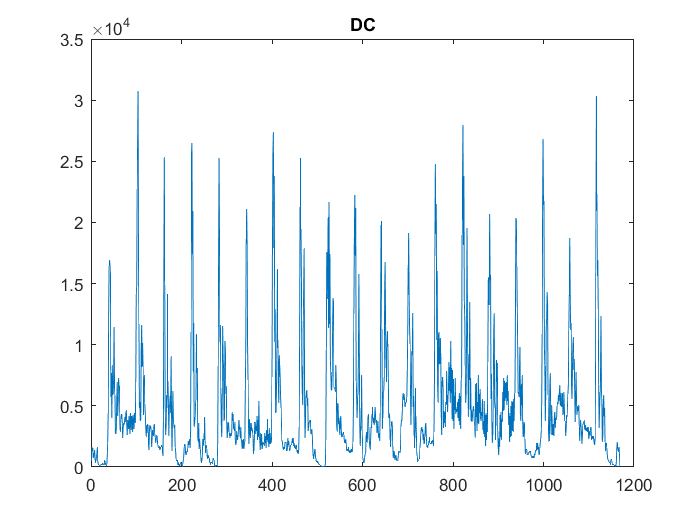

plot(DC)
title('DC');


RDC=xcorr(DC)

RDC = 	1.0e+10 *

   -0.0000    0.0000    0.0000    0.0002    0.0005    0.0006    0.0008    0.0009    0.0012    0.0013    0.0012    0.0010    0.0009    0.0009    0.0010    0.0010    0.0009    0.0009    0.0009    0.0009    0.0009    0.0008    0.0007    0.0006    0.0006    0.0006    0.0007    0.0008    0.0008    0.0008    0.0010    0.0013    0.0016    0.0017    0.0018    0.0021    0.0027    0.0034    0.0042    0.0049    0.0062    0.0087    0.0117    0.0150    0.0188    0.0206    0.0213    0.0208    0.0204    0.0201


NDC=length(DC) 

NDC = 1170

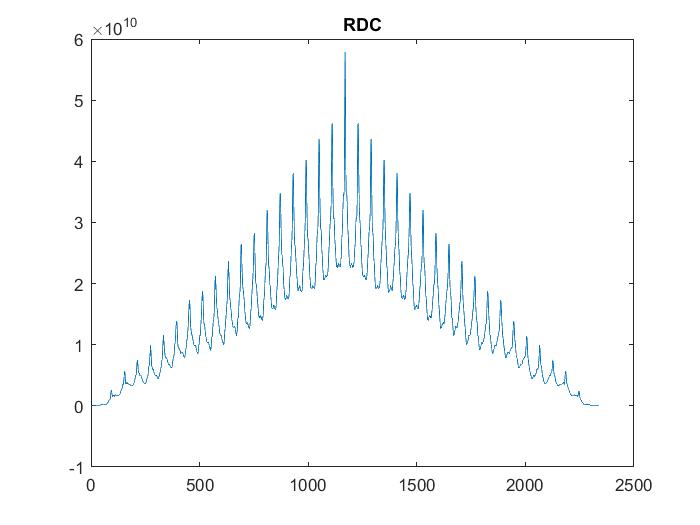


plot(RDC)
title('RDC');


[pks,locs]=findpeaks(RDC)

pks = 	1.0e+10 *

    0.0013    0.0010    0.0009    0.0213    0.0297    0.0269    0.1055    0.2457    0.1696    0.1788    0.1827    0.1783    0.1707    0.5566    0.3906    0.3563    0.3434    0.5044    0.7437    0.5403    0.4960    0.3889    0.3706    0.4876    0.9844    0.6021    0.4967    0.4888    0.4453    1.1450    0.7907    0.7922    0.7696    0.6732    1.3841    0.9521    0.8685    0.8691    0.8728    0.8699    1.7206    0.9842    0.9912    0.9911    1.1634    1.8738    1.0369    2.1159    1.1527    1.1507


locs =     10    16    21    47    56    67    86    94   101   104   111   115   121   155   165   175   183   206   214   222   230   242   249   260   275   286   301   303   309   334   344   346   350   361   394   405   416   418   420   422   454   477   479   481   502   514   541   573   598   600


p=maxk(pks, 2)

p = 	1.0e+10 *

    5.7832    4.6190


A1=find(pks==min(p),1,"last") %κελι στον πινακα pks

A1 = 105

A2=find(pks==max(p)) %κελι στον πινακα pks

A2 = 96


B1=locs(1,A1) %θεση δευτερης μεγαλυτερης κορυφης

B1 = 1230

B2=locs(1,A2) %θεση μεγαλυτερης κορυφη

B2 = 1170


distance=abs(B2-B1)

distance = 60


SDC=distance*512*ovrlp

SDC = 7680


seconds=SDC/Fs*1

seconds = 0.4800


bpm=60/seconds

bpm = 125


%Στο διαδίκτυο βρίσκουμε ότι τα bpm του seven nation army είναι 125. Αφού
%χρησιμοποιήσαμε τις διάφορες μεθοδολογίες παρατηρούμε ότι τα bpm και των
%τριών κυματομορφών είναι τα ίδια και ακριβώς 125. Αυτό σημαίνει ότι και οι
%τρεις κυματομορφές είναι πολύ ακριβείς για το συγκεκριμένο κομμάτι.